# Plik inicjalizacyjny dla nadajnika i odbiornika QPSK

## Czyszczenie workspace'a

clc
clear
r = findPlutoRadio

r = 1×2 struct array with fields:
    RadioID
    SerialNum


## Definicja bitratu

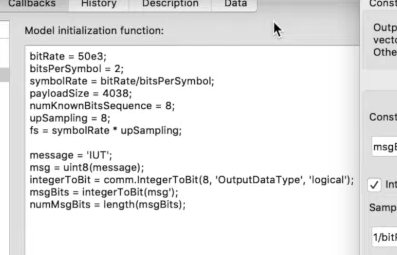\

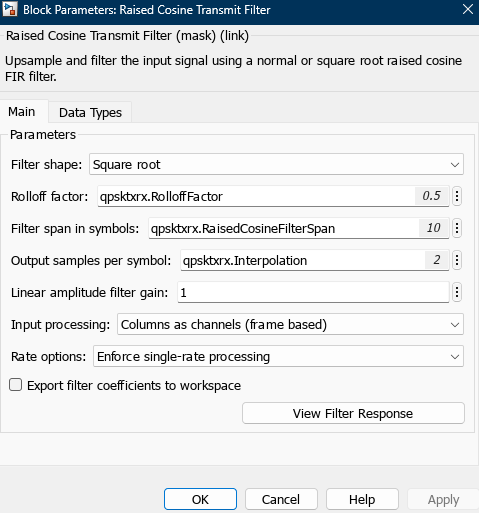

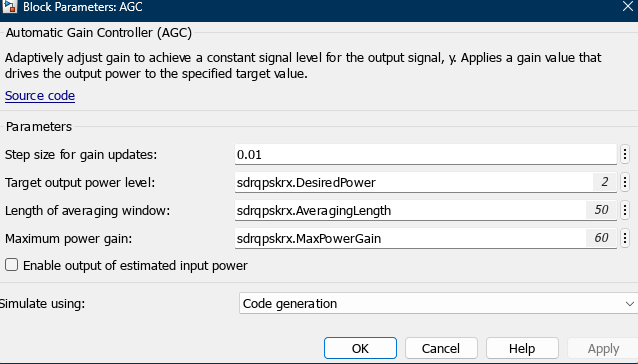

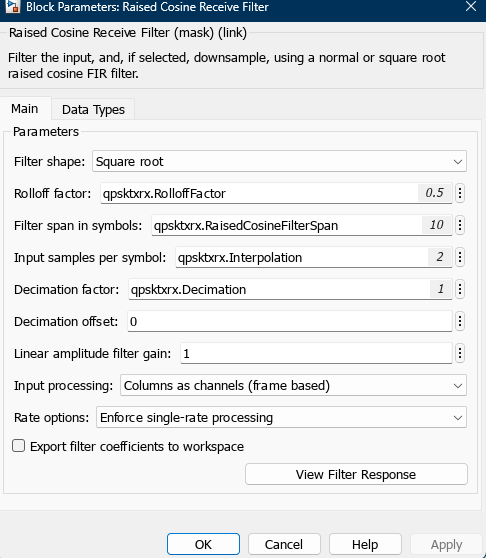

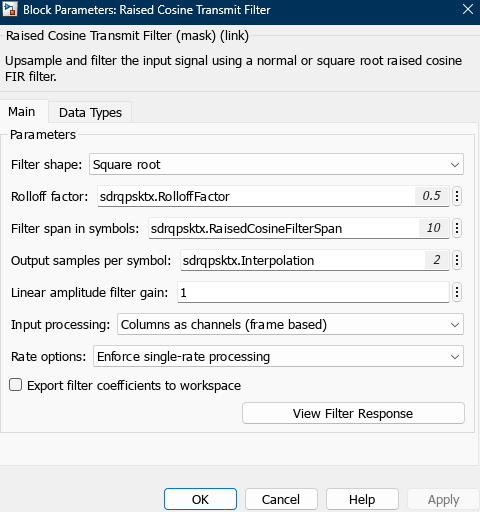

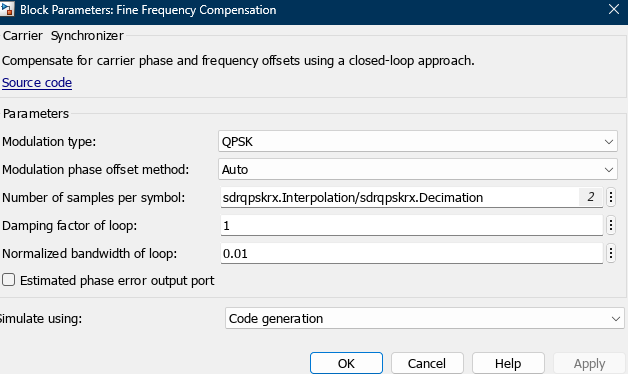

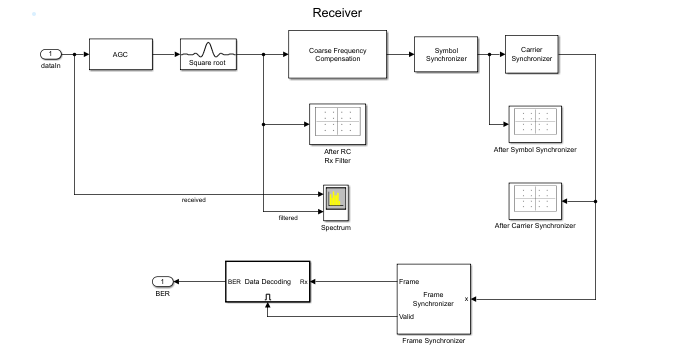

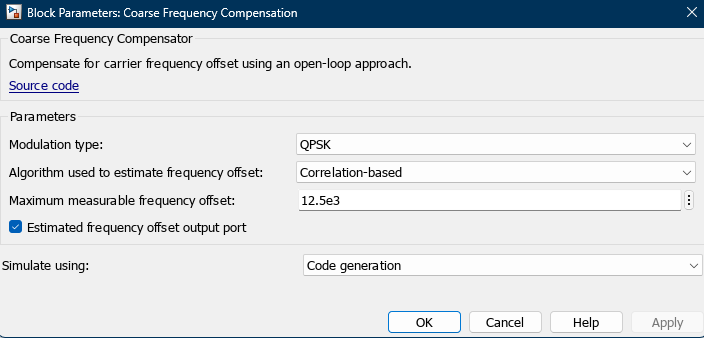

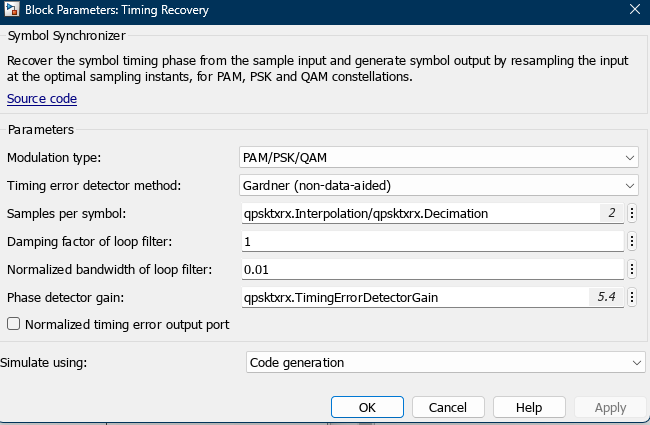

bitRate = 50e3;
bitsPerSymbol = 2;
symbolRate = bitRate/bitsPerSymbol;
dlugosc_w = 128;
randomowe_bity = randi([0,1],4096-2*13-8-dlugosc_w,1);
numConstBitsSequence = 8;
upSampling = 8;
sampleRate = 8*25e3;
fs = symbolRate*upSampling;

## Definicja zmiennej częstotliwości nadajnika i odbiornika

f = Simulink.Parameter;
f.Value = 1.8e9;
f.CoderInfo.StorageClass = 'SimulinkGlobal';

## Definicja zmiennej częstotliwości jammera

fjam = Simulink.Parameter;
fjam.Value = 2e9;
f.CoderInfo.StorageClass = 'SimulinkGlobal';

## Definicja zmiennej wiadomości

wiadomosc = Simulink.Parameter;
wiadomosc.Value = "Test";
wiadomosc.DataType = 'string';
wiadomosc.CoderInfo.StorageClass = 'ExportedGlobal';

## Uruchomienie modeli symulinkowych

open_system('Nadajnik_pluto_qpsk');
open_system('Odbiornik_pluto_qspk');
% open_system('Zagluszarka_pluto_qpsk');
